# Analyze results of nonlinear performance simulation

## Commanded values

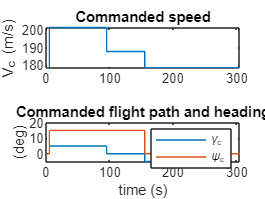

figure
subplot(2,1,1);
plot( ... 
    soCommanded.Time, soCommanded.Data(:,1), '-' ...
)
xlabel(''); ylabel('V_c (m/s)')
title('Commanded speed')
subplot(2,1,2);
plot( ... 
    soCommanded.Time, soCommanded.Data(:,2)*57.3, '-', ...
    soCommanded.Time, soCommanded.Data(:,3)*57.3, '-' ...
)
xlabel('time (s)'); ylabel('(deg)')
title('Commanded flight path and heading')
legend('\gamma_c', '\psi_c')

## Consumed mass

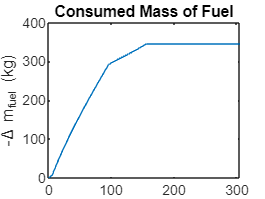

figure
plot( ...
    soMass.Time, (mass_0/u.kg - soMass.Data), '-' ...
)
ylabel('-\Delta m_{fuel} (kg)')
title('Consumed Mass of Fuel')

## Thrust and drag

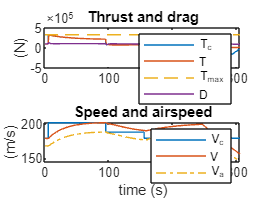

figure
subplot(2,1,1);
plot( ... 
    soThrustC.Time, soThrustC.Data, '-', ...
    soThrust.Time, soThrust.Data, '-', ...
    [soThrust.Time(1),soThrust.Time(end)], ...
        [thrustMax, thrustMax]/u.N, '--', ...
    soDrag.Time, soDrag.Data, '-' ...
)
xlabel(''); ylabel('(N)')
legend('T_c', 'T', 'T_{max}', 'D')
title('Thrust and drag')
subplot(2,1,2);
plot( ... 
    soCommanded.Time, soCommanded.Data(:,1), '-', ...
    soSpeedAirspeedHdot.Time, soSpeedAirspeedHdot.Data(:,1), '-', ...
    soSpeedAirspeedHdot.Time, soSpeedAirspeedHdot.Data(:,2), '-.' ...
)
xlabel('time (s)'); ylabel('(m/s)')
legend('V_c', 'V', 'V_{a}')
title('Speed and airspeed')

## Lift, AoA, flight path angle

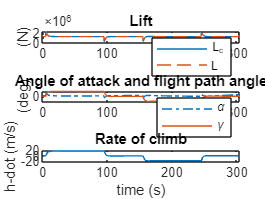

figure
subplot(3,1,1);
plot( ... 
    soLiftCLiftAlpha.Time, soLiftCLiftAlpha.Data(:,1), '-', ...
    soLiftCLiftAlpha.Time, soLiftCLiftAlpha.Data(:,2), '--' ...
)
xlabel(''); ylabel('(N)')
legend('L_c', 'L')
title('Lift')
subplot(3,1,2);
plot( ... 
    soLiftCLiftAlpha.Time, soLiftCLiftAlpha.Data(:,3)*57.3, '-.', ...
    soFlightPathAngle.Time, soFlightPathAngle.Data*57.3, '-' ...
)
xlabel(''); ylabel('(deg)')
title('Angle of attack and flight path angle')
legend('\alpha', '\gamma')
subplot(3,1,3);
plot( ... 
    soSpeedAirspeedHdot.Time, soSpeedAirspeedHdot.Data(:,3), '-' ...
)
xlabel('time (s)'); ylabel('h-dot (m/s)')
title('Rate of climb')

## Heading and bank angle

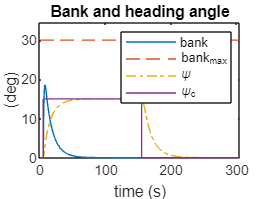

figure
plot( ... 
    soBankAngle.Time, soBankAngle.Data*57.3, '-', ...
    [soBankAngle.Time(1),soBankAngle.Time(end)], ...
        [bankAngleMax, bankAngleMax]/u.deg, '--', ...
    soHeadingAngle.Time, soHeadingAngle.Data*57.3, '-.', ...
    soCommanded.Time, soCommanded.Data(:,3)*57.3, '-' ...
)
ylim([0, 1.15*bankAngleMax/u.deg])
xlabel('time (s)'); ylabel('(deg)')
legend('bank', 'bank_{max}', '\psi', '\psi_c')
title('Bank and heading angle')

**TRAJECTORY AND EULER ANGLES**

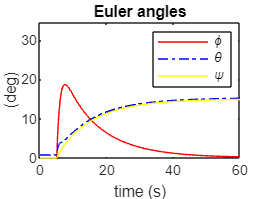

t_trajectory=60;
vTime = linspace(0,t_trajectory,400);

vXe = interp1(xe_ye_ze_delta_gamma.Time,xe_ye_ze_delta_gamma.Data(:,1),vTime,'pchip');
vYe = interp1(xe_ye_ze_delta_gamma.Time,xe_ye_ze_delta_gamma.Data(:,2),vTime,'pchip');
vh =  interp1(xe_ye_ze_delta_gamma.Time,xe_ye_ze_delta_gamma.Data(:,3),vTime,'pchip');
vZe = -vh;
vDelta = interp1(xe_ye_ze_delta_gamma.Time,xe_ye_ze_delta_gamma.Data(:,4),vTime,'pchip');
vGamma = interp1(xe_ye_ze_delta_gamma.Time,xe_ye_ze_delta_gamma.Data(:,4),vTime,'pchip');
vNu = interp1(soBankAngle.Time, soBankAngle.Data,vTime,'pchip');
vAlphaB = interp1(soLiftCLiftAlpha.Time, soLiftCLiftAlpha.Data(:,3),vTime,'pchip');


Rot3 = @(angle) [cos(angle)   sin(angle)   0;
                -sin(angle)   cos(angle)   0;
                     0            0        1];                
Rot2 = @(angle) [cos(angle)    0   -sin(angle);
                     0         1        0;
                 sin(angle)    0    cos(angle)];             
Rot1 = @(angle) [1       0            0;
                 0   cos(angle)   sin(angle);
                 0  -sin(angle)   cos(angle)];
              
vPsi = zeros(length(vTime),1);
vTheta = zeros(length(vTime),1);
vPhi = zeros(length(vTime),1);
vQuat=zeros(length(vTime),4);

 for i = 1:length(vTime)
     
     TBE = Rot2(vAlphaB(i))*Rot1(vNu(i))*Rot2(vGamma(i))*Rot3(vDelta(i));
     [psi,theta,phi] = dcm2angle(TBE,'ZYX');
     quat = angle2quat(psi,theta,phi,'ZYX');
     vPsi(i) = psi;
     vTheta(i) = theta;
     vPhi(i) = phi;
     vQuat(i,1) = quat(1);
     vQuat(i,2) = quat(2);
     vQuat(i,3) = quat(3);
     vQuat(i,4) = quat(4);
 end


figure
plot( ... 
    vTime, vPhi*57.3, 'r-',...
    vTime, vTheta*57.3, 'b-.', ...
    vTime, vPsi*57.3, 'y-' ...
)
ylim([0, 1.15*bankAngleMax/u.deg])
xlabel('time (s)'); ylabel('(deg)')
legend('\phi', '\theta', '\psi')
title('Euler angles')

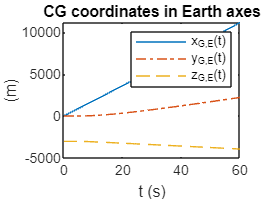





figure
plot( ...
    vTime,vXe, '-',...
    vTime,vYe, '-.', ...
    vTime,vZe, '--' ...
    )

legend('x_{G,E}(t)','y_{G,E}(t)','z_{G,E}(t)')
xlabel('t (s)'); ylabel('(m)');
title('CG coordinates in Earth axes');





h_fig3=figure(10);
grid on;
hold on;
light('Position',[1 0 -4],'Style','local');
% Trick to have Ze pointing downward and correct visualization
set(gca,'XDir','reverse');
set(gca,'ZDir','reverse');
daspect([1 1 1]);

%% Load aircraft shape
shapeScaleFactor = 350.0;
%shape = loadAircraftMAT('aircraft_pa24-250.mat', scale_factor);
shape = loadAircraftMAT('aircraft_mig29.mat', shapeScaleFactor);

mXYZe = [vXe',vYe',vZe'];
mEulerAngles = [vPsi,vTheta,vPhi];

%% Settings
% General settings
options.samples = [1,61,111,141:50:numel(vTime)]; %[1,40,80,120,160,200,250,300,320,numel(vTime)];
options.theView = [105 15];

% body axes settings
options.bodyAxes.show = true;
options.bodyAxes.magX = 1.5*shapeScaleFactor;
options.bodyAxes.magY = 2.0*shapeScaleFactor;
options.bodyAxes.magZ = 2.0*shapeScaleFactor;
options.bodyAxes.lineWidth = 2.5;

% helper lines
options.helperLines.show = true;
options.helperLines.lineStyle = ':';
options.helperLines.lineColor = 'k';
options.helperLines.lineWidth = 1.5;

% trajectory
options.trajectory.show = true;
options.trajectory.lineStyle = '-';
options.trajectory.lineColor = 'k';
options.trajectory.lineWidth = 1.5;

%% Plot body and trajectory
plotTrajectoryAndBodyE(h_fig3, shape, mXYZe, mEulerAngles, options);

plotTrajectoryAndBodyE -- Visualization loop:
index: 1
index: 61
index: 111
index: 141
index: 191
index: 241
index: 291
index: 341
index: 391


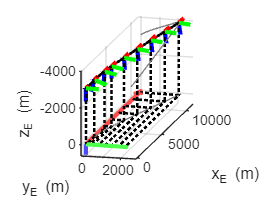


%% Plot Earth axes
hold on;
xMax = max([max(abs(mXYZe(:,1))),5]);
yMax = max([max(abs(mXYZe(:,2))),5]);
zMax = 0.05*xMax; % max([abs(max(vXYZe(1))),0.18*xMax]);
vXYZ0 = [0,0,0];
vExtent = [xMax,yMax,zMax];
plotEarthAxes(h_fig3, vXYZ0, vExtent);
xlabel('x_E (m)'); ylabel('y_E (m)'); zlabel('z_E (m)')
hold off